# **Matriz de observabilidad**

Considere el siguiente sistema de transmisión de un automovil:

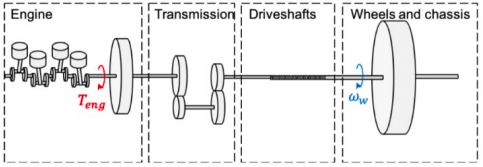

El sistema está descripto por las siguientes ecuaciones en espacio de estados:

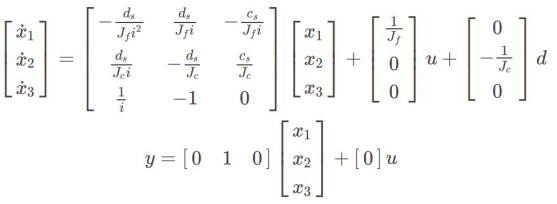

donde x1 es la velocidad del motor, x2 es la velocidad en las ruedas, x3 es el torque en árbol de transmisión (driveshafts), Δu es la señal de entrada, el torque del motor, y Δd1 es la perturbación, las variaciones en la superficie de la calzada. 

Los parámetros del modelo son: 

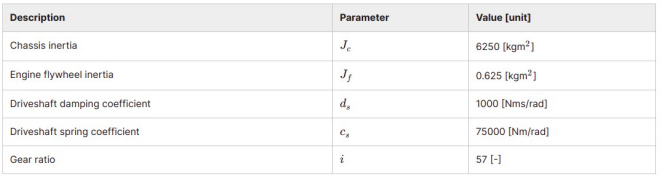

**1)** Encuentre la matriz de observabilidad. ¿Es el sistema observable?

close all; clear all; clc;
% Parámetros númericos.
Jc = 6250;
Jf = 0.625;
ds = 1000;
cs = 75000;
i = 57;
% Matrices númericas.
A = [-ds/(Jf*i^2)  ds/(Jf*i) -cs/(Jf*i);
     ds/(Jc*i)    -ds/Jc      cs/Jc;
     1/i          -1          0];
Bu = [1/Jf;0;0];
Bd = [0;-1/Jc;0];
B = Bu + Bd;
C = [0 1 0];
D = [0];
observabilidad = obsv(A,C); % Matriz de observabilidad.
if rank(observabilidad) == 3
    fprintf('Rango de la matriz de observabilidad para C = [0 1 0]: ')
    disp(rank(observabilidad))
    fprintf('Sistema observable.\n')
end

Rango de la matriz de observabilidad para C = [0 1 0]: 

     3



Sistema observable.


**2)** Verifique si el sistema es observable para C = [1 0 0] , C = [0 1 0] y C = [0 0 1]. 

Cprima = [1 0 0];
observabilidad = obsv(A,Cprima); % Matriz de observabilidad.
if rank(observabilidad) == 3
    fprintf('Rango de la matriz de observabilidad para C = [1 0 0]: ')
    disp(rank(observabilidad))
    fprintf('Sistema observable.\n')
else
    fprintf('El sistema no es observable para C = [1 0 0],\nesto implica que no podremos estimar los estados\ninternos del sistema a partir de sensar la velocidad\ndel motor.\n')
end

Rango de la matriz de observabilidad para C = [1 0 0]: 

     3



Sistema observable.



Cprimaprima = [0 0 1];
observabilidad = obsv(A,Cprimaprima); % Matriz de observabilidad.
if rank(observabilidad) == 3
    fprintf('Rango de la matriz de observabilidad para C = [0 0 1]: ')
    disp(rank(observabilidad))
    fprintf('Sistema observable.\n')
else
    fprintf('El sistema no es observable para C = [0 0 1],\nesto implica que no podremos estimar los estados\ninternos del sistema a partir de sensar el torque del\narbol del motor.\n')
end

El sistema no es observable para C = [0 0 1],
esto implica que no podremos estimar los estados
internos del sistema a partir de sensar el torque del
arbol del motor.


**3) **Luego de analizar los 3 escenarios posibles de observabilidad, ¿qué sensor o sensores de salida elegiría para este sistema?

Resulta evidente que para sensar la salida del sistema elegiriamos un sensor de velocidad ya sea para la rueda o para las revoluciones del motor del vehículo, para asi poder estimar el estado interno del sistema.

Para decidir si es más recomendable sensar la velocidad de las ruedas o la velocidad de giro del motor para estimar el estado interno del sistema, es importante considerar varios factores.

- **Sensibilidad a las perturbaciones**: La velocidad de las ruedas puede verse afectada por perturbaciones externas, como cambios en la superficie de la carretera o la adherencia de los neumáticos. Por otro lado, la velocidad de giro del motor puede ser más robusta a estas perturbaciones, ya que está más directamente relacionada con el funcionamiento interno del vehículo. En términos de sensibilidad a perturbaciones, sensar la velocidad de giro del motor podría ser más recomendable.

- **Información sobre el desempeño del sistema**: La velocidad de las ruedas puede proporcionar información valiosa sobre el desempeño del sistema en términos de aceleración, frenado y cambios de dirección. Si se necesita monitorear y controlar estos aspectos específicos del sistema, sensar la velocidad de las ruedas puede ser más relevante y útil.

- **Disponibilidad y costo de los sensores**: Se debe considerar la disponibilidad y el costo de los sensores necesarios para medir tanto la velocidad de las ruedas como la velocidad de giro del motor.  Se debe además verificar la facilidad de instalación y mantenimiento de los sensores en el vehículo. Si uno de los sensores es más accesible y económico que el otro, eso también podría influir en la elección.

En general, no hay una respuesta definitiva ya que la elección depende de las especificaciones y los requisitos del sistema en particular. Se recomienda analizar los factores mencionados anteriormente y evaluar cuál de las dos opciones se ajusta mejor a las necesidades específicas en términos de sensibilidad a perturbaciones, información requerida y factibilidad práctica.